# Perform Instance Segmentation Using Mask R-CNN

## Load Pretrained Network

dataFolder = fullfile(tempdir,"coco");
trainedMaskRCNN_url = "https://www.mathworks.com/supportfiles/vision/data/maskrcnn_object_person_car_v2.mat";
downloadTrainedMaskRCNN(trainedMaskRCNN_url,dataFolder);
load(fullfile(dataFolder,"maskrcnn_object_person_car_v2.mat"));

## **Segment People in Image**

imTest = imread("visionteam.jpg");
[masks,labels,scores,boxes] = segmentObjects(net,imTest,Threshold=0.98);

overlayedImage = insertObjectMask(imTest,masks);
imshow(overlayedImage)

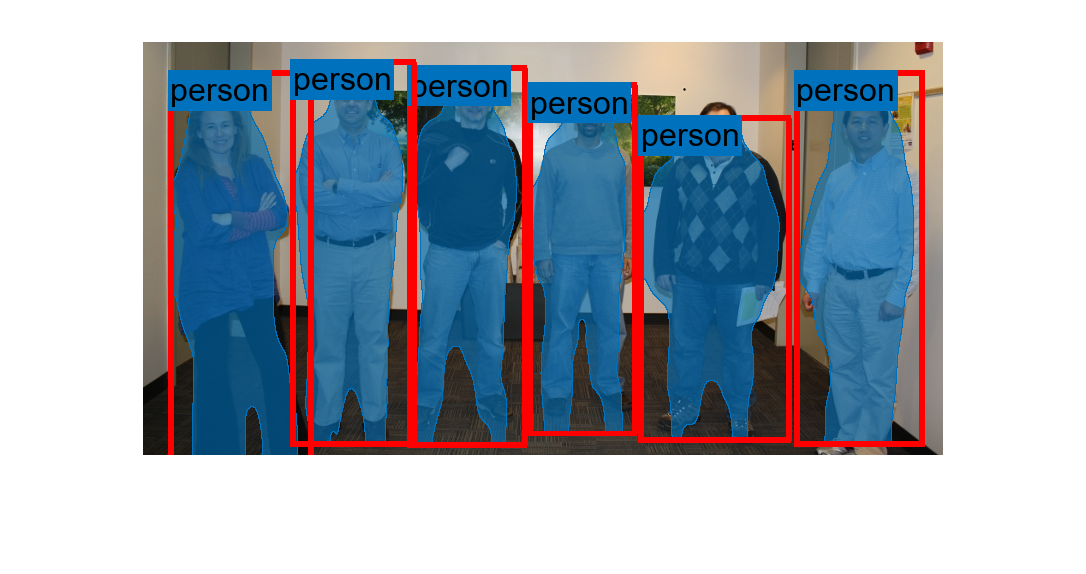

showShape("rectangle",gather(boxes),Label=labels,LineColor="r")

## Load Training Data

imageFolder = fullfile(dataFolder,"images");
captionsFolder = fullfile(dataFolder,"annotations");
if ~exist(imageFolder,"dir")
    mkdir(imageFolder)
    mkdir(captionsFolder)
end

annotationFile = fullfile(captionsFolder,"instances_train2014.json");
str = fileread(annotationFile);

## Prepare Data for Training

trainClassNames = ["person","car"];
numClasses = length(trainClassNames);
imageSizeTrain = [800 800 3];

### Format COCO Annotation Data as MAT Files

cocoAPIDir = fullfile(dataFolder,"cocoapi-master","MatlabAPI");
addpath(cocoAPIDir);

unpackAnnotationDir = fullfile(dataFolder,"annotations_unpacked","matFiles");
if ~exist(unpackAnnotationDir,'dir')
    mkdir(unpackAnnotationDir)
end
unpackAnnotations(trainClassNames,annotationFile,imageFolder,unpackAnnotationDir);

### Create Datastore

ds = fileDatastore(unpackAnnotationDir, ...
    ReadFcn=@(x)cocoAnnotationMATReader(x,imageFolder));

data = preview(ds)

## Configure Mask R-CNN Network

net = maskrcnn("resnet50-coco",trainClassNames,InputSize=imageSizeTrain)

data = 1×4 cell array
    {428×640×3 uint8}    {16×4 double}    {16×1 categorical}    {428×640×16 logical}


## Train Network

options = trainingOptions("sgdm", ...

net =   maskrcnn with properties:

      ModelName: 'maskrcnn'
     ClassNames: {'person'  'car'}
      InputSize: [800 800 3]
    AnchorBoxes: [15×2 double]


    InitialLearnRate=0.001, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropPeriod=1, ...
    LearnRateDropFactor=0.95, ...
    Plot="none", ...
    Momentum=0.9, ...
    MaxEpochs=10, ...
    MiniBatchSize=2, ...
    BatchNormalizationStatistics="moving", ...
    ResetInputNormalization=false, ...
    ExecutionEnvironment="gpu", ...
    VerboseFrequency=50);

doTraining = true;
if doTraining
    [net,info] = trainMaskRCNN(ds,net,options,FreezeSubNetwork="backbone");
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm-ss"));
    save("trainedMaskRCNN-"+modelDateTime+".mat","net");
end